**AnalysisPipelineBuilder App**

**Purpose**

AnalysisPipelineBuilder is an App that allows you to construct pipelines to analyze your data and store and export the results. Please read the "Pipelines" section of the Overview doc so that you are familiar with the concept before proceeding through this section. 

**Opening the App**

To open the app call it from the command line:

AnalysisPipelineBuilder;

Error using matlab.apps.internal.GraphicsCallbackProxy/runCallbackFunction (line 23)
Error while evaluating GraphicsCallbackProxy CallbackFcn.



Before you can get into the main window, this will open up the PipelineSelector window that looks like this.

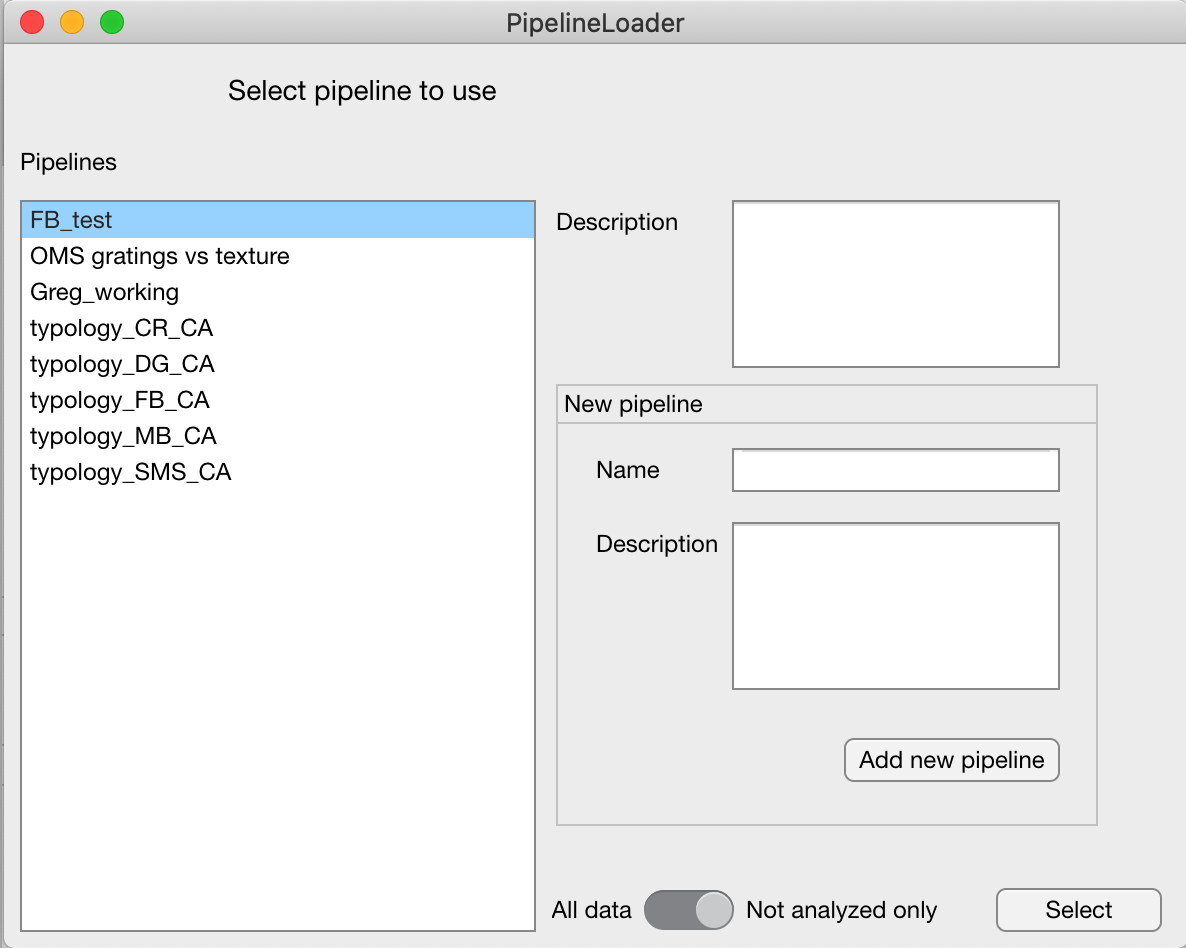

In this window, you can select a pipelline to load or you can add a new one first and then select it. 

Add a new pipeline so you an start playing around with the features of the App. To do so, type a name and description in the "New pipeline" panel and then press "Add new pipeline". Then your new pipeline should appear in the list on the left. For playing around with different data, I suggest keeping a blank "working" pipeline named something like "Greg_working". 

Once you select your pipeline from the list, you can decide to open it with "All data" or "Not analyzed data". This is just a view setting that can be changed inside the main App. For your new blank pipeline this makes no difference, but eventually you may have a large input query, and it could be faster to open the App in a view that only shows the new "unanalyzed" data. Press "Select" to dismiss the PipelineLoader window and reveal the main App window.

**Parts of the pipeline / panels of the App**

The main window looks like this. 

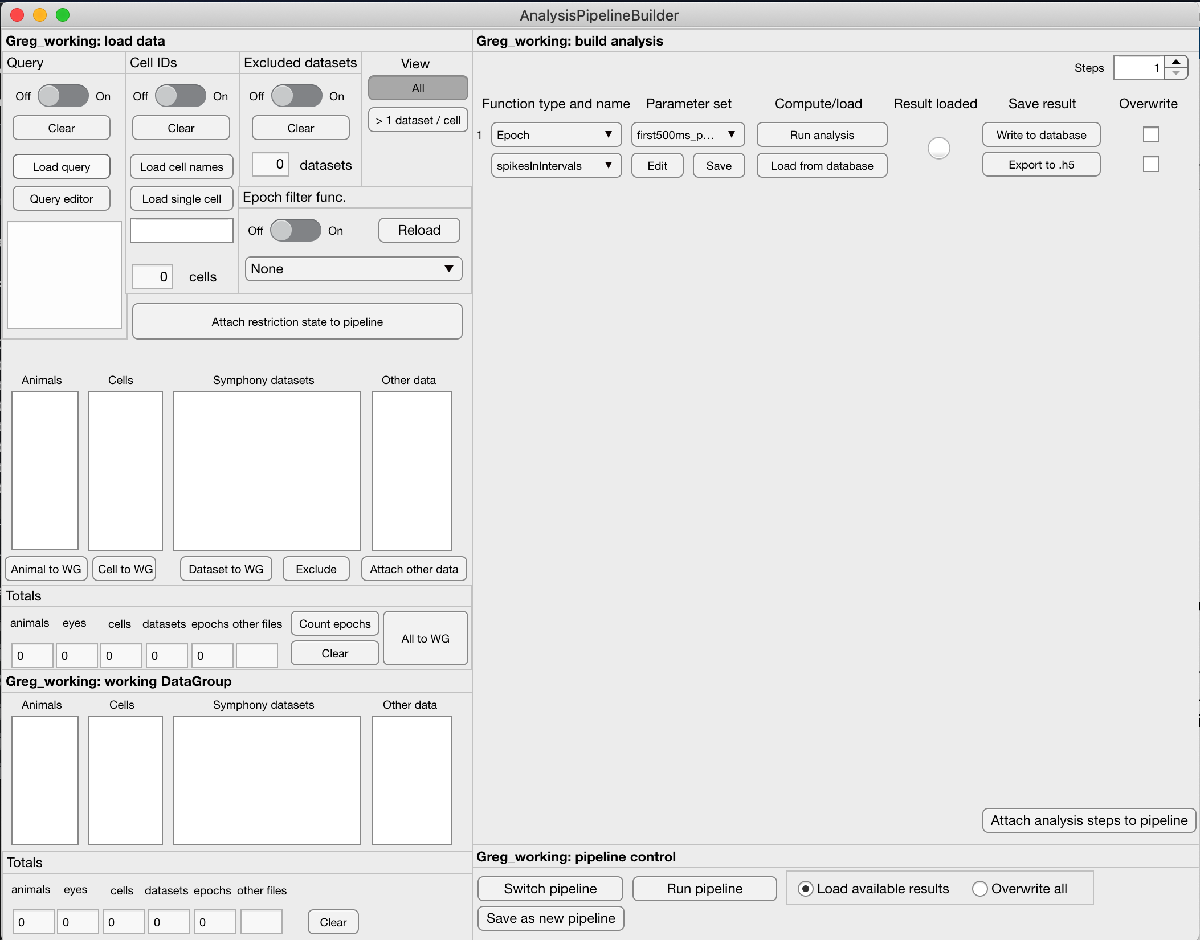

I realize there is a lot going on here! First, note different "panels" in the app. The left side has the "load data" and "working DataGroup" panels and the right side has the "build analysis" and "pipeline control" panels. These first 3 panels are each associated with a different part of the pipeline and the control panel is for running the whole thing or switching to a new pipeline. I will review the parts of the pipeline and tell you where each is stored in the database. Then I will show you how they are manipulated in the app. 

**Input query**

The input query for your pipeline determines the group of Datasets that that provide the input to your analysis. 

The pipeline name, description text, and the owner (user who created it) are stored in 

sl.Pipeline

ans = Object sl.Pipeline

 :: Analysis Pipeline ::

           PIPELINE_NAME                                                                                  pipeline_description                                                                               owner   
    ___________________________    ___________________________________________________________________________________________________________________________________________________________________    ___________

    {'FB_test'                }    {0×0 char                                                                                                                                                         }    {'sl_user'}
    {'Greg_working'           }    {'working test pipeline'                                                                                                                                          }    {

If you run that command, you should see some of the stored pipelines. 

The actual input query will be stored in 

sl_mutable.PipelineQuery

ans = Object sl_mutable.PipelineQuery

 :: PipelineQuery stores the single loading query for each analysis pipeline ::

       PIPELINE_NAME                                                             query_str                                                          epoch_filter_func    use_query    use_cell_id_list    use_epoch_filter    use_dataset_exclusion    query_state    cell_id_list
    ___________________    _____________________________________________________________________________________________________________________    _________________    _________    ________________    ________________    _____________________    ___________    ____________

    {'typology_SMS_CA'}

When you press the big button labeled "Attach restriction state to pipeline" all the settings in the "load data" panel are stored here, overwriting anything that was there before. When you load a pipeline, it will read in the settings from this table if there is an entry for your pipeline. Thus, sl_mutable.PipelineQuery can only have either zero or one entries for each pipeline. 

Four methods together define your input query

Note that there are 4 sub-panels in the "load data" panel. The "View" section is NOT one of them; it controls the data you are viewing in the App but not what is stored in the pipeline. Each of the 4 sub-panels has an ON-OFF switch. ON means that the information in this panel will be used to restrict the data coming into your pipeline, OFF means that it will not be used. 

**Query**

This is the main way you should specify your input query. It will allow you to condition on any set of attributes in a variety of tables including sl.Animal, sl.MeasuredCell, sl.SymphonyRecordedCell, sl.CurrentCellType, and sl.Dataset. You can load a query stored in a .mat file with the "load query button" or edit the currently loaded query by pressing the "Query editor" button. This will open the QueryEditor App that is covered in a separate document. Once a query has either been loaded or been run in the QueryEditor App and that App is closed, a text version of the query will appear in the text box below. The query text is not directly editable. 

**Cell IDs**

This panel allows you to restrict the pipeline input directly by a set of cell_ids. You can load them using a .txt file in which each cell_id appears on its own line or you can enter one cell at a time manually in the text box and press the "Load single cell" button. The counter at the bottom of the panel keeps a running count of the number of cells you have entered. Note that if you restrict your pipeline by cell_ids, you will not be able to discover new data automatically. Instead, you will have to manually add the new cell_ids.

**Excluded datasets**

Sometimes you will want to exclude specific datasets in a way that is not easily amenable to a query. For example, some datasets are named by a specific drug condition or occured after ablation. In cases like these, you can exclude datasets individually from a pipeline. The "Exclude" button below the SymphonyDatasets listbox alllows you to add single, selected datasets to the exclusion list. IMPORTANT: you must have the animal and cell_id selected as well (in their corresponding list boxes) so you can fully specify the dataset you want to exclude. Dataset exclusions are specific to each pipeline. They are stored in

sl_mutable.DatasetExcludeList

ans = Object sl_mutable.DatasetExcludeList

 :: DatasetExcludeList table stores datasets excluded from particular pipelines ::

       PIPELINE_NAME       CELL_UNID    ANIMAL_ID       CELL_ID         CELL_DATA                DATASET_NAME              CHANNEL
    ___________________    _________    _________    _____________    _____________    ________________________________    _______

    {'typology_FB_CA' }       373           16       {'101620Ac5'}    {'101620Ac5'}    {'FlashedBar_length400'        }       1   
    {'typology_SMS_CA'}       390           94       {'022119Ac4'}    {'022119Ac4'}    {'SpotsMultiSize_uv'           }       1   
    {'typology_SMS_CA'}       399          101       {'060116Ac6'}    {'060116Ac6'}    {'SpotsMultiSize_5s'  

The counter at the bottom of the panel keeps a running count of the number of datasets on the exclude list for this pipeline.

**Epoch filter func. **

This should be used as a last resort because it is MUCH SLOWER than the other three forms of restriction, but it is also very flexible. You can write a function that will run on each epoch in each dataset pared down from your other exclusion criteria and return a pass/fail value about whether to include it. Datasets in which ALL epochs fail your test will be exccluded from your pipeline. For example, MovingBar datasets have been run with different bar speeds, and we have not been consistent about inluding the bar speed in the name of the dataset. So, if you want ONLY datasets that include a bar at speed 1000, you could use this EpochFilterFunction.

There is a folder for EpochFilterFunctions inside the main DJ folder (see the FolderSetup document) where these are stored, and this will populate the dropdown menu. If you write a new EpochFilterFunction, you can reload the menu with the "Reload" button instead of restarting the App. They must be written in this form: a single input will be the struct corresponding to a fetch('*') command on an epoch, and the single output must take a value of 0 or 1 (not BOOL true/false because DJ does not handle BOOL variables internally yet). 

View controls

You will find two "state" button under the word "View" on the right side of the "load data" panel. Along with your input query, these buttons determine which Datasets appear in the list boxes below. The top button toggles between the "All" state at the "Unanalyzed" state where your view is restricted to Datasets that have not yet been analyzed in this pipeline. An automaticallly generated list of datasets that have been analyzed for each pipeline can be found in this table. 

sl_mutable.DatasetAnalyzed

ans = Object sl_mutable.DatasetAnalyzed

 :: DatasetAnalyzed table stores datasets for which analysis is completed for a pipeline ::

      PIPELINE_NAME       CELL_UNID    ANIMAL_ID       CELL_ID          CELL_DATA             DATASET_NAME           CHANNEL          entry_time       
    __________________    _________    _________    ______________    ______________    _________________________    _______    _______________________

    {'typology_CR_CA'}       396           99       {'051019Ac4' }    {'051019Ac4' }    {'ContrastResponse'     }       1       {'2021-01-15 08:52:00'}
    {'typology_CR_CA'}       399          101       {'060116Ac6' }    {'060116Ac6' }    {'ContrastResp_size100' }       1       {'2021-01

Since you are the owner of your own pipelines, you are free to delete entries from this table for your pipeline if you want certain Datasets to show up as unanalyzed again. Look up Datajoint documentation on the "del" command. 

The bottom state button toggles between the "All" state and the "> 1 dataset / cell" state. For some pipelines, you might want to make sure there is only one Dataset analyzed per cell. Toggling to the "> 1 dataset / cell" state will allow you to view cells with > 1 Dataset matching your query so that you can exclude the extra ones if you wish to. 

NOTE: the text on state buttons like this does not show the current state, but instead shows the state that you will sitch TO by pressing the button.

Loaded data viewer and controls

The bottom half of the "load data" panel is for viewing a list of the Datasets that passed your input query and for sending some or all of them to the WorkingGroup. Any change in your input query will reset all of the list boxes to show a full list. The total numbers of animals, eyes, cells, datasets, epochs, and other files in your input query is listed in the "Totals" sub-panel. NOTE: The number of epochs is not automatically calculated because that step can be kind of slow, like maybe 5-10 seconds for a large input query with thousands of epochs. Just press the "Count epochs" button to update the count.

Selecting an Animal in the animal list box will update the other list boxes to show only Cells and Datasets belonging to that Animal. Similarly, selecting a Cell in the cells list box will update the Datasets list box to show only Datasets for that Cell. IMPORTANT: This behavior is just for your own view. It does not change the input query. Thus, your selections in these list boxes will not affect the "Totals" numbers below. 

Clear button

This will clear out the current input query. NOTE: None of the changes you make to the input query, including clearing it out, are saved to your pipeline until and unless you press the "Attach restriction state to pipeline" button. So if you hit "Clear" or anything else by mistake, just reload your pipeline (with the "Switch pipeline" button in the "pipeline control" panel) and nothing will have changed from its saved state. 

"to WG" buttons

Under each list box is a button that allows you to send some of the input query Datasets to the WorkingGroup. You can send over single Datasets, all Datasets for a Cell or all Cells and Datasets for an Animal. IMPORTANT: You must make a valid selection in all list boxes at the levels above the one for which you press the "to WG" button. For example, to send a single Dataset to the WorkingGroup, you must have the corresponding Cell and Animal selected as well BEFORE you press the "Dataset to WG" button. You can send the entire input query to the WorkingGroup with the "All to WG" button in the "Totals" sub-panel. NOTE: Sending Datasets to the WorkingGroup does not remove them from the input query. 

Other data

This feature is not implemented yet. It's a placeholder for the future. In some cases, data from outside Symphony will be needed for an analysis that we will still want stored in the database. For example, Sophia's unccaging experiments will use some image analysis to determine the distance of each uncaging site from the soma. That distance number is important to her analysis, but it cannot be inferred from the Symphony Dataset alone. Thus, she will record it in a different file that is then attached to her datasets. I plan on adding a table to the database to associate external data like this with particular Datasets, Cells, and Pipelines.

**The working DataGroup**

The working DataGroup panel is for viewing the subset of the input query that you are currently working on analyzing in the GUI. It is a TEMPORARY set of Datasets in the sense that it is not stored in the database and it will be initialized to empty every time you open the App. Its main purpose is for you to have a manageable set of Datasets (often one at a time) on which to test out your analysis pipeline to make sure it is working before you run it on a larger set of data. The list boxes in the "Working DataGroup" panel work the same way as those in the "load data" panel. The computation, loading, and export buttons in the "build analysis" panel will run analysis, load, and export results, respectively, ONLY from the working DataGroup. 